Hi there! In this live script, we are gonna show how does Lab2 of Image Processing work. 

Let's start by adding the share folder.

addpath('./share')  

## Introduction. Complex Numbers in MATLAB

Matlab work naturally with the floating point representation of complex numbers.  The accuracy is about 16 decimal digits.  Try to understand the results of the following:

sqrt(-1)

ans = 0.0000 + 1.0000i


i^2

ans = -1


exp(i*pi)

ans = -1.0000 + 0.0000i


x = 1i^(1/3)

x = 0.8660 + 0.5000i


[real(x), imag(x), abs(x), angle(x)*180/pi]

ans =     0.8660    0.5000    1.0000   30.0000


You can relate the obtained results with the following image relating the Euler's formula:

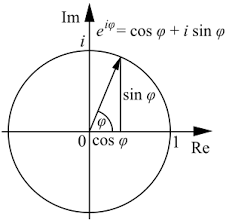

## Experiments with Fourier transforms

In Matlab we use the fft2() function calculates the fast Fourier transform of an image, and the ifft2() function to calculates the inverse transform.

During the seminar 3 we have computed the fourier transform of several 2D signals, that can be seen as an image. Let's try to compute the same fourier transform and relate the results:

First we define the 2D signal:

x = zeros(2,3); x(1,1) = 100

x =    100     0     0
     0     0     0


Let's compute the fourier transforms of the 2D signal:

fx = fft2(x)

fx =    100   100   100
   100   100   100


And now the inverse of the fourier transform:

ifft2(fx)

ans =    100     0     0
     0     0     0


First we define the 2D signal:

x = zeros(2,3); x(1,2) = 100

x =      0   100     0
     0     0     0


Let's compute the fourier transforms of the 2D signal:

fx = fft2(x)

fx = 	1.0e+02 *

   1.0000 + 0.0000i  -0.5000 - 0.8660i  -0.5000 + 0.8660i
   1.0000 + 0.0000i  -0.5000 - 0.8660i  -0.5000 + 0.8660i


And now the inverse of the fourier transform:

ifft2(fx)

ans =      0   100     0
     0     0     0


## Visualization of the Fourier transform

The Fourier transform of a small matrix could be analyzed by direct inspection of each matrix entry (these numbers are generally complex). But for visualization a large matrix of complex numbers must be somehow transformed into a real image. Some part of information is inevitably lost.  During this lab, we propose to apply the transformation $z=\log \left(1+\left|z\right|\right)$ (but there are many other ways of visualization).  

Let us define this transformation in code. 

For example, the definition could be:

Furthermore, we propose to define an auxiliary function for normalizing the values of a matrix to fall within 0 and 1.

During the lab session, it would be convenient that you create a function file for each function you will use often, like for example logvis and normalize. In this case I have created both functions for you. Nonetheless, you will need to create those functions too in your exercises.

Using these two functions we can more easily visualize the Fourier transforms:

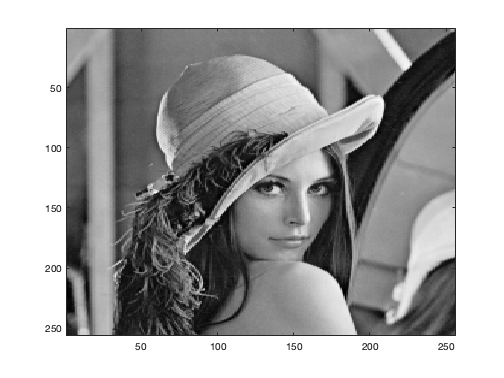

% Read the image and convert it to double
x = double(imread('image processing/Lab2-2022/lena.png'));
%x = x(:,:,1)
%x = rgb2gray(x)
% Show the image
figure; imagesc(x); colormap gray;

% compute the fourier transform
fx = fft2(x);
% show the fourier transform of the image 
% with the transformation explained
% below
figure; imagesc(normalize(logvis(fx))); colormap gray;

It is common "to center" the Fourier transform so that the origin of coordinates remains in the center of the image, instead of the upper left corner.

The function *fftshift* from matlab performs this shift.  Combining all these functions, we define a function to display Fourier transforms:

show_f(fx)

## Interpretation of the Fourier transform.

The smoother an image is, that is, the lower frequencies it has, the more its spectrum is concentrated around the origin. In the extreme case of a constant image, the only one non-zero value of the spectrum is at the origin. If an image is very noisy or has periodic high frequency components, the spectrum is more dispersed. For example, if you compare the following image of barbara to the image of lena, barbara image contains higher frequencies than the   lena image  (high frequencies correspond to the periodic texture of the striped dress and the wicker chair):

% Read the image and convert it to double
x2 = double(imread('image processing/Lab2-2022/barbara.png'));
% be sure is one channel image
x2 = x2(:,:,1);
%x2 =rgb2gray(x2)
% Show the image
figure; imagesc(x2/255); colormap gray;
% compute the fourier transform
fx2 = fft2(x2);
show_f(fx2)

## Frequency Filters

The simplest application of the frequency domain is the direct editing of an image frequencies. The *low-pass *filter  aims to eliminate high frequencies and the *high-pass* filter aims to eliminate low frequencies. The *band-pass *filter retain only frequencies within a certain range.

It is important to familiarize yourself with the effects that these filters produce on images. We provide a function claled* lpfilter *that creates a filter, which is simply a binary mask that is then applied to the frequencies:

%define low pass filter
low_pass = lpfilter('ideal', 256, 256, 13);
% the high pass filter is 
% the inverse to the low pass filter
high_pass = 1 - low_pass;

% Let's visualize them
show_f(low_pass);
show_f(high_pass);
% Let's visualize the fourier transform 
% of the image lena when the low pass filter
% or high pass filter is applied
show_f(fx .* low_pass);
show_f(fx .* high_pass);

% Let's apply the inverse of 
% the fourier transform
fx_low = ifft2(fx .* low_pass);
fx_high = ifft2(fx .* high_pass);

% Let's visualize the results
figure;
imagesc(fx_low); colormap gray;
figure;
imagesc(fx_high); colormap gray;
figure;
imagesc(fx_low + fx_high); colormap gray;

You can see that the filtering sometimes has not a very good quality.

This is called ringing or Gibbs phenomenon, and it happens because a binary mask is not smooth.  

Later,  we will study this phenomenon in more details, and see how this issue can be solved by using Gaussian masks instead of a binary ones as we used in the last example.

On the other hand, band-pass filters can be obtained by combining two low-pass filters of different frequencies:

fa = lpfilter('gaussian', 256, 256, 40);
fb = lpfilter('gaussian', 256, 256, 50);
band_pass = fb - fa;
show_f(band_pass);
fx_band = ifft2(fx .* band_pass);
figure; show_f(fx .* band_pass)
figure;
imagesc(fx_band); colormap gray;

## Sampling, aliasing, ringing, geometry of sampling

The operator ``:'' in Matlab greatly facilitates the implementation of sampling.:

% Array from 1 to 10 with a separation of one value.
1:10
% Array from 1 to 10 with a separation of two value.
1:2:10
% Array from 1 to 10 with a separation of three value.
1:3:10

% Create a random 1D signal
x = rand(10,10)
% Take just the first 5 values
x(1:5)
% Subsampling of factor two.
x(1:2:10,1:2:10)

This operator can be used to reduce the size of images (with loss of resolution).

 x = im2double(imread('lena.png'));
 size(x)
 imshow(x)
 x_half = x(1:2:256,1:2:256);
 size(x_half)
 imshow(x_half)
 x_third = x(1:3:256,1:3:256);
 size(x_third)
 imshow(x_third)
 x_quarter = x(1:4:256,1:4:256);
 size(x_quarter)
 imshow(x_quarter)

## Interpretation of sampling in the frequency space

In theory session you have seen that sampling in the spatial domain corresponds to the *folding* in the frequency domain (produce replications of the spectrum that can be layered or *folded*).

In the case of one dimension, it can be seen that:

 % Random 1D signal of size N
 N = 10
 x = rand(N,1)
 % Compute the fourier transform
 fx = fft(x)
 % middle position of the signal
 mid_N = N/2
 % Folding
 fx_small = (fx(1:mid_N) + fx(mid_N+1:N))/2
 % inverse transform
 x_folded = ifft(fx_small)
 % Subsampling
 x_2 = x(1:2:10)
 % diference between signal and subsmapling
 x_folded - x_2
 % Keep in mind that the results is close to 0 
 % because is multiplyied by 10^{-15}

You should understand perfectly the meaning of the above commands, and the results given.

## Lab 2!

You can find the questions in the pdf.

 
%EXERCICI 1a --------------------------------------------------

img = im2double(imread('image processing/Lab1/lena.png'));

%Fem la trandformada de Fourier i apliquem les funcions logvis i normalize
f_img = fft2(img);
f_shift = ifftshift(f_img);
show_f(f_shift);

Unrecognized function or variable 'show_f'.

normalize(logvis(f_img));

%Substituim els valors del pixels de soroll per un pixel de color negre
fas = lpfilter('ideal', size(img2,1), size(img2,2), 33);
show_f(fas);
lena_fourier = f_shift .*fas;
%Fem la antitransformada de Fourier i apliquem de nou les funcions
new_img2 = normalize(logvis(ifft2(lena_fourier)));
imshow(new_img2);

%EXERCICI 1b ---------------------------------------------------
img2 = im2double(imread('lena_verynoisy2.png'));
show_f(img2);
%transformada de Fourier
f_img2 = ifftshift(fft2(img2));
show_f(f_img2);



%filtre passa banda
fa = lpfilter('ideal', size(img2,1), size(img2,2), 33);
fb = lpfilter('ideal', size(img2,1), size(img2,2), 34);
band_pass = 1 - (fb - fa);
show_f(band_pass);
shift_bp = fftshift(band_pass);
show_f(shift_bp);


lena_fourier = f_img2 .*shift_bp;

show_f(lena_fourier);

new_img2 = normalize(logvis(ifft2(lena_fourier)));
imshow(new_img2);



%EXERCICI 2 -- SUBSAMPLING------------------------------------------------------
pantalons = im2double(imread('ipantalons.jpg'));


%FACTOR 2
factor = 2;
f_pantalons = fft2(pantalons);

%Creem el filtre passa-baixos i l'apliquem a Fourier
low_pass = lpfilter('ideal', size(pantalons,1), size(pantalons,2), (size(pantalons,1)/(factor*2)));
low_pantalons = low_pass.*f_pantalons;

%Fem la antitransformada de Fourier
new_pantalons = ifft2(low_pantalons);

subsampled_newpantalons = new_pantalons(1:factor:size(new_pantalons,1),1:factor:size(new_pantalons,2));
figure; imshow(subsampled_newpantalons);

%FACTOR 4
factor = 4;
f_pantalons = fft2(pantalons);

%Creem el filtre passa-baixos i l'apliquem a Fourier
low_pass = lpfilter('ideal', size(pantalons,1), size(pantalons,2), (size(pantalons,1)/(factor*2)));
low_pantalons = low_pass.*f_pantalons;

%Fem la antitransformada de Fourier
new_pantalons = ifft2(low_pantalons);

subsampled_newpantalons = new_pantalons(1:factor:size(new_pantalons,1),1:factor:size(new_pantalons,2));
figure; imshow(subsampled_newpantalons);

%FACTOR 8
factor = 8;
f_pantalons = fft2(pantalons);

%Creem el filtre passa-baixos i l'apliquem a Fourier
low_pass = lpfilter('ideal', size(pantalons,1), size(pantalons,2), (size(pantalons,1)/(factor*2)));
low_pantalons = low_pass.*f_pantalons;

%Fem la antitransformada de Fourier
new_pantalons = ifft2(low_pantalons);

subsampled_newpantalons = new_pantalons(1:factor:size(new_pantalons,1),1:factor:size(new_pantalons,2));
figure; imshow(subsampled_newpantalons);


%------ EXERCICI 3 --------------------------------------------------------

x = [ 0 0 0 0 0 1 1 1 1 1 ];
y = [ 0 0 0 0 1 0 0 0 0 0 ];

%OFFSET 1
offset = 1;
f_x = fft(x);
N = length(x);
centre = (N/2)+1;
multipliers = zeros(1,length(x));

for i = 1:length(x)
    multipliers(i) = exp(-2 * pi * 1j * (i - centre) * (offset/N));
end

ifftshift(multipliers);
ck = f_x .*multipliers;
x_new = ifft(ck);
disp(x_new);

%OFFSET 0.5
offset = 0.5;
f_x = fft(x);
N = length(x);
centre = (N/2)+1;
multipliers = zeros(1,length(x));

for i = 1:length(x)
    multipliers(i) = exp(-2 * pi * 1j * (i - centre) * (offset/N));
end

ifftshift(multipliers);
ck = f_x .*multipliers;
x_new = ifft(ck);
disp(x_new);

%OFFSET 0.1
offset = 0.1;
f_x = fft(x);
N = length(x);
centre = (N/2)+1;
multipliers = zeros(1,length(x));

for i = 1:length(x)
    multipliers(i) = exp(-2 * pi * 1j * (i - centre) * (offset/N));
end

ifftshift(multipliers);
ck = f_x .*multipliers;
x_new = ifft(ck);
disp(x_new);

%------ EXERCICI OPCIONAL ---------------------------------------------------

Barbara = im2double(imread('Barbara.png'));
Mcqueen = im2double(imread('Mcqueen.png'));

%transformades de Fourier
im1_f = ifftshift(fft2(Barbara));
im2_f = ifftshift(fft2(Mcqueen));

%filtres
low_pass = lpfilter('ideal', size(Barbara,1), size(Mcqueen, 2), 30);
high_pass = 1 - low_pass;

%apliquem filtre opció 1
result1_a = (low_pass.* im1_f ); %Barbara passa baixos amb radi 0.3
result2_a = (im2_f .* high_pass); %Mcqueen passa alts amb radi 0.7

%merge
final_a = (result1_a + result2_a); 
new_img_a = normalize(logvis(ifft2(final_a)));

%apliquem el filtre opció 2
result1_b = (im1_f .* high_pass); %Barbara passa alts amb radi 0.7
result2_b = (im2_f .* low_pass); %lMcqueen baixos amb radi 0.3

%merge
final_b = (result1_b + result2_b); %Barbara amb filtre passa alts i Mcqueen amb filtre passa baixos
new_img_b = normalize(logvis(ifft2(final_b)));

imshow(new_img_a);
imshow(new_img_b);



